## 以PA1为模型，探究单级DPD的线性化能力

## -----------------------------Read Data----------------------------

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Original();
% 根据需要选取原始数据
PA1_x_i=Data_matrix(:,3);PA1_x_q=Data_matrix(:,4);
PA1_y_i=Data_matrix(:,7);PA1_y_q=Data_matrix(:,8);
PA1_input = PA1_x_i + 1i * PA1_x_q; 
PA1_output = PA1_y_i + 1i * PA1_y_q; 

## Algorithm 1:Feedforward Neural Network

% 设置输入/输出矩阵
M=2; % 记忆深度
X = zeros(2*(M + 1), dim-M); 
for j = 1:length(PA1_y_i) - M
    X(:, j) = [PA1_y_i(j : j + M); PA1_y_q(j : j + M)];
end 
Y = [PA1_x_i(M + 1 : end)'; PA1_x_q(M + 1 : end)']; 
% 调整参数和训练模型
net = feedforwardnet(5);% 神经元数量 
FNN = train(net, X, Y);
% 查看单级DPD的模型性能
Y_pred = sim(FNN, X); 
a = Y_pred(1, :) + Y_pred(2, :) * 1i; % PA输出预测值
b = Y(1, :) + Y(2, :) * 1i; % PA输出值（）
nmse_DPD = NMSE_dB(a, b);
fprintf('单级DPD的NMSE为 %f dB', nmse_DPD);

单级DPD的NMSE为 -26.857803 dB

单级DPD的NMSE为 -18.751428 dB

｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量　ＲＭＳＥ　　｜　　验证　ＲＭＳＥ　　｜　　小批量损失　　｜　　验证损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：００：０１　｜　　　　　　　０．７８　｜　　　　　　０．７６　｜　　０．３０７０　｜　０．２９２４　｜　　０．００５０　｜
｜　５００　｜　　５００　｜　　　　　００：００：０４　｜　　　　　　　０．０２　｜　　　　　　０．０２　｜　　０．０００３　｜　０．０００３　｜　　０．００５０　｜
｜　１０００　｜　１０００　｜　　　　　００：００：０６　｜　　　　　　　０．０２　｜　　　　　　０．０２　｜　　０．０００２　｜　０．０００２　｜　　０．００２５　｜
｜　１５００　｜　１５００　｜　　　　　００：００：０９　｜　　　　　　　０．０２　｜　　　　　　０．０２　｜　　０．０００２　｜　０．０００２　｜　　０．００１２　｜
｜　２０００　｜　２０００　｜　　　　　００：００：１１　｜　　　　　　　０．０２　｜　　　　　　０．０２　｜　　０．０００１　｜　０．０００１　｜　　０．０００６　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
训练结束: 已完成最大轮数。


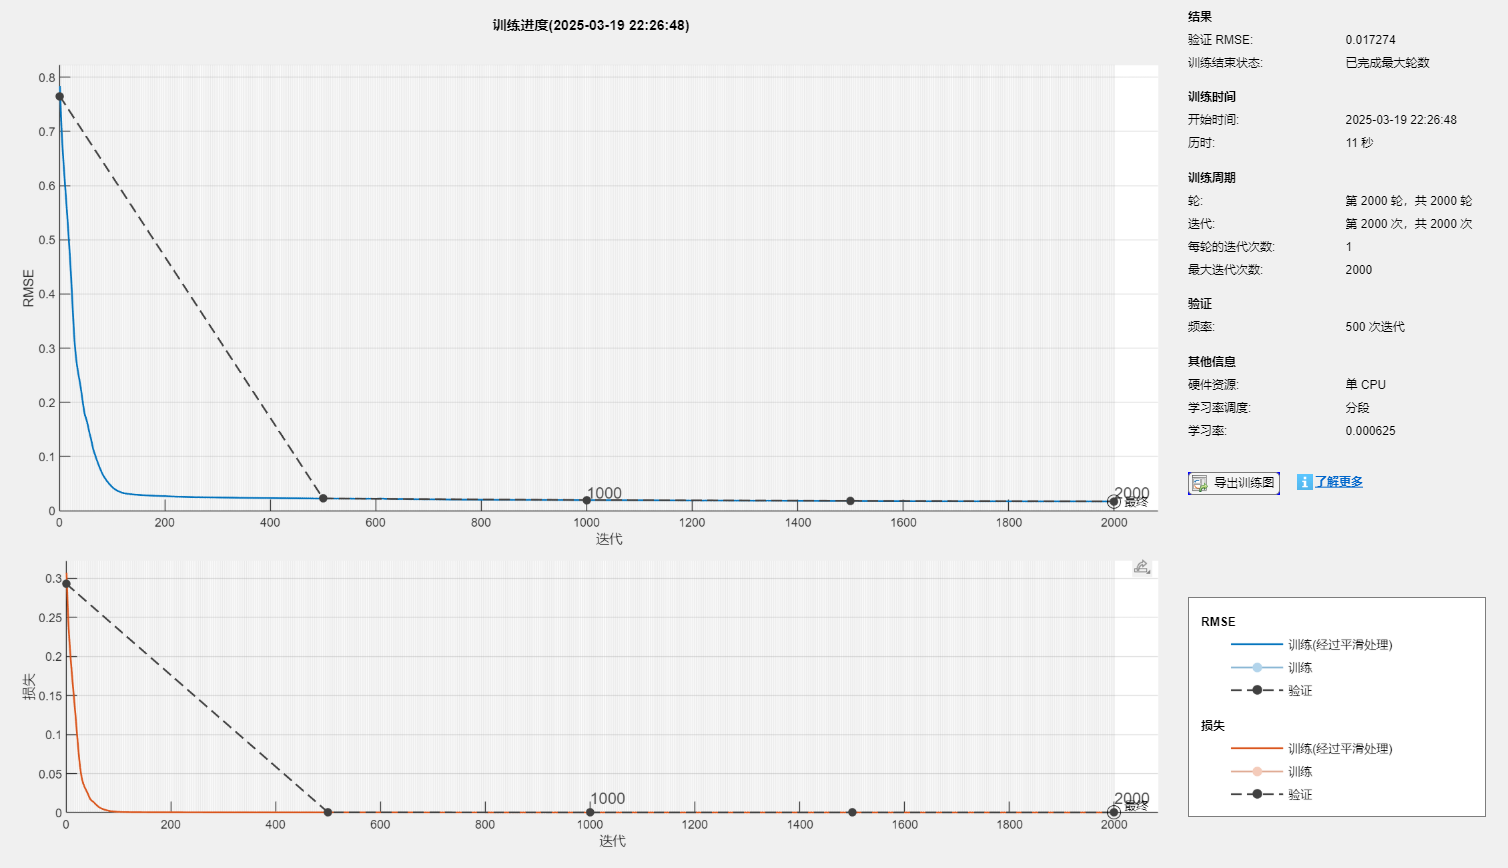

单级DPD的NMSE为 -25.464111 dB


save('Algorithm_A/Alg_PA1.mat', 'FNN');